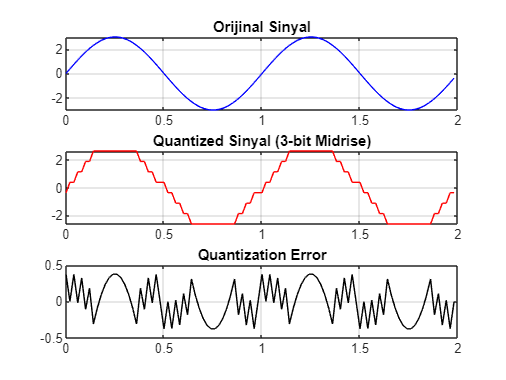

%% (a)(i) Midrise Quantizer Uygulaması


Fs = 50;              
T = 2;                
f = 1;               
A = 3;               
num_bits = 3;         

% Zaman vektörü ve sinyal üretimi
n = 0:1/Fs:T-(1/Fs);          
x = A * sin(2*pi*f*n);       


num_levels = 2^num_bits;
x_max = max(abs(x(:)));                     
delta = 2*x_max / num_levels;              
reconstruction_levels = -x_max + delta/2 : delta : x_max - delta/2;


[~, idx] = min(abs(x(:) - reconstruction_levels), [], 2);  
xq = reconstruction_levels(idx);                          


x = x(:);        
xq = xq(:);      


error = x - xq;
snr = 10 * log10(sum(x.^2) / sum(error.^2));


figure;
subplot(3,1,1);
plot(n, x, 'b'); title('Orijinal Sinyal'); grid on;

subplot(3,1,2);
plot(n, xq, 'r'); title('Quantized Sinyal (3-bit Midrise)'); grid on;

subplot(3,1,3);
plot(n, error, 'k'); title('Quantization Error'); grid on;



fprintf('Midrise Quantizer SNR: %.2f dB\n', snr);

Midrise Quantizer SNR: 18.63 dB


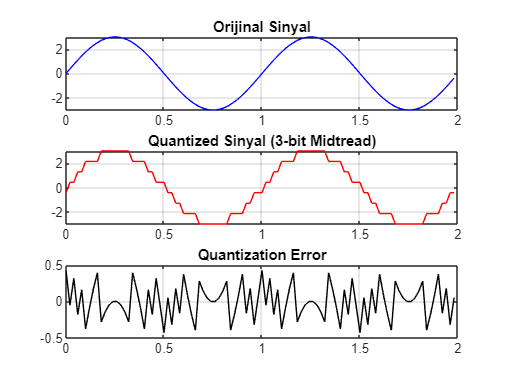




%% (a)(ii) Midtread Quantizer Uygulaması


Fs = 50;              
T = 2;                
f = 1;                
A = 3;                
num_bits = 3;         

% Zaman vektörü ve sinyal üretimi
n = 0:1/Fs:T-(1/Fs);          
x = A * sin(2*pi*f*n);       

% Midtread quantizer hesaplaması
num_levels = 2^num_bits;
x_max = max(abs(x(:)));                    
delta = 2*x_max / (num_levels - 1);      
reconstruction_levels = -x_max : delta : x_max; 

% Kuantizasyon işlemi
[~, idx] = min(abs(x(:) - reconstruction_levels), [], 2);  
xq = reconstruction_levels(idx);                           

% Sinyal ve kuantize sinyali sütun vektör haline getir
x = x(:);        
xq = xq(:);      

% Kuantizasyon hatası ve SNR
error = x - xq;
snr = 10 * log10(sum(x.^2) / sum(error.^2));

% Sonuçları çiz
figure;
subplot(3,1,1);
plot(n, x, 'b'); title('Orijinal Sinyal'); grid on;

subplot(3,1,2);
plot(n, xq, 'r'); title('Quantized Sinyal (3-bit Midtread)'); grid on;

subplot(3,1,3);
plot(n, error, 'k'); title('Quantization Error'); grid on;


% SNR değerini yazdır
fprintf('Midtread Quantizer SNR: %.2f dB\n', snr);

Midtread Quantizer SNR: 19.13 dB





%%(b) Signal Level Mismatch ile SNR Karşılaştırması (Midrise Quantizer)

% Parametreler
Fs = 50; T = 2; f = 1; A = 3; num_bits = 3;
n = 0:1/Fs:T-(1/Fs);
x = A * sin(2*pi*f*n);     

% İki yeni sinyal üret (çarpanlı)
x1 = 0.5 * x;             
x2 = 2 * x;                

% Midrise quantizer ayarları (orijinal sinyale göre tasarlanmış)
num_levels = 2^num_bits;
x_max = max(abs(x(:)));              
delta = 2 * x_max / num_levels;
reconstruction_levels = -x_max + delta/2 : delta : x_max - delta/2;

% --- x1[n] için ---
[~, idx1] = min(abs(x1(:) - reconstruction_levels), [], 2);  
xq1 = reconstruction_levels(idx1);
error1 = x1(:) - xq1(:);
snr1 = 10 * log10(sum(x1(:).^2) / sum(error1.^2));

% --- x2[n] için ---
[~, idx2] = min(abs(x2(:) - reconstruction_levels), [], 2);  
xq2 = reconstruction_levels(idx2);
error2 = x2(:) - xq2(:);
snr2 = 10 * log10(sum(x2(:).^2) / sum(error2.^2));


fprintf('x1[n] = 0.5 * x[n] için SNR: %.2f dB\n', snr1);

x1[n] = 0.5 * x[n] için SNR: 12.69 dB


fprintf('x2[n] = 2 * x[n] için SNR: %.2f dB\n', snr2);

x2[n] = 2 * x[n] için SNR: 6.28 dB


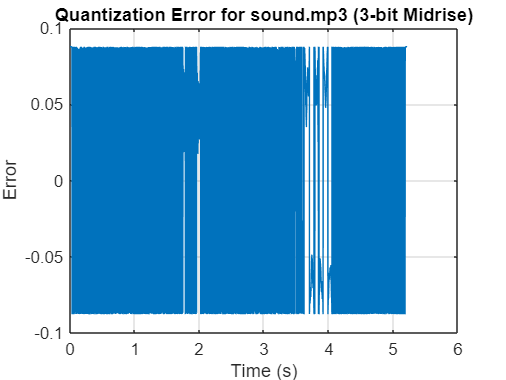



%%(c) sound.mp3 için 3-bit Midrise Quantizer


[soundData, Fs] = audioread('C:\Users\mehme\Desktop\lab3_prelab\sound.mp3');

%%[soundData, Fs] = audioread('sound.mp3');


if size(soundData,2) > 1
    soundData = soundData(:,1); 
end

% 3-bit midrise quantizer ayarları
num_bits = 3;
num_levels = 2^num_bits;
x_max = max(abs(soundData(:)));
delta = 2*x_max / num_levels;
reconstruction_levels = -x_max + delta/2 : delta : x_max - delta/2;

% Kuantizasyon işlemi
[~, idx] = min(abs(soundData(:) - reconstruction_levels), [], 2);
quantized = reconstruction_levels(idx);

% Hata ve SNR
error = soundData(:) - quantized(:);
snr = 10 * log10(sum(soundData(:).^2) / sum(error.^2));

% Hata sinyalini çiz
t = (0:length(soundData)-1)/Fs;
figure;
plot(t, error); title('Quantization Error for sound.mp3 (3-bit Midrise)');
xlabel('Time (s)'); ylabel('Error'); grid on;


% SNR çıktısı
fprintf('Sound.mp3 için 3-bit Midrise Quantizer SNR: %.2f dB\n', snr);

Sound.mp3 için 3-bit Midrise Quantizer SNR: 6.46 dB


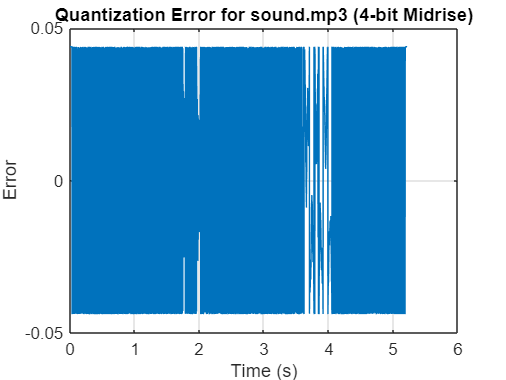


% Sesleri dinle

soundsc(soundData, Fs);
pause(3);


soundsc(quantized, Fs);


%%(d) sound.mp3 için 4-bit Midrise Quantizer

% Ses dosyasını oku
[soundData, Fs] = audioread('C:\Users\mehme\Desktop\lab3_prelab\sound.mp3');
%%[soundData, Fs] = audioread('sound.mp3');

% Sadece 1 kanal kullan (mono hale getir)
if size(soundData,2) > 1
    soundData = soundData(:,1); 
end

% 4-bit midrise quantizer ayarları
num_bits = 4;
num_levels = 2^num_bits;
x_max = max(abs(soundData(:)));
delta = 2*x_max / num_levels;
reconstruction_levels = -x_max + delta/2 : delta : x_max - delta/2;

% Kuantizasyon işlemi
[~, idx] = min(abs(soundData(:) - reconstruction_levels), [], 2);
quantized = reconstruction_levels(idx);

% Hata ve SNR
error = soundData(:) - quantized(:);
snr = 10 * log10(sum(soundData(:).^2) / sum(error.^2));

% Hata sinyalini çiz
t = (0:length(soundData)-1)/Fs;
figure;
plot(t, error); title('Quantization Error for sound.mp3 (4-bit Midrise)');
xlabel('Time (s)'); ylabel('Error'); grid on;


% SNR çıktısı
fprintf('Sound.mp3 için 4-bit Midrise Quantizer SNR: %.2f dB\n', snr);

Sound.mp3 için 4-bit Midrise Quantizer SNR: 13.17 dB



% Sesleri dinle
disp('Orijinal ses çalınıyor...');

Orijinal ses çalınıyor...


soundsc(soundData, Fs);
pause(3);

disp('Kuantize ses çalınıyor...');

Kuantize ses çalınıyor...


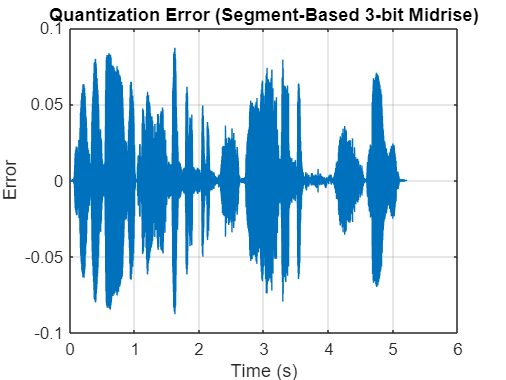

soundsc(quantized, Fs);


%%(e) Segment Bazlı 3-bit Midrise Quantization

% Ses dosyasını oku
[soundData, Fs] = audioread('C:\Users\mehme\Desktop\lab3_prelab\sound.mp3');
%%[soundData, Fs] = audioread('sound.mp3');

% Mono hale getir
if size(soundData,2) > 1
    soundData = soundData(:,1); 
end

% Segment ayarları
segmentLength = 100;
num_bits = 3;
num_levels = 2^num_bits;

% Sinyal uzunluğu
N = length(soundData);
num_segments = ceil(N / segmentLength);

% Kuantize edilmiş sinyalin saklanacağı yer
quantized = zeros(size(soundData));

% Segment bazlı kuantizasyon
for i = 1:num_segments
    idx_start = (i-1)*segmentLength + 1;
    idx_end = min(i*segmentLength, N);
    
    segment = soundData(idx_start:idx_end);
    xmax = max(abs(segment));
    
    % Sessiz segment kontrolü
    if xmax == 0
        quantized(idx_start:idx_end) = 0;
        continue;
    end
    
    delta = 2*xmax / num_levels;
    levels = -xmax + delta/2 : delta : xmax - delta/2;
    
    [~, idx] = min(abs(segment(:) - levels), [], 2);
    quantized(idx_start:idx_end) = levels(idx(:)); 
end  % ← Eksik END buradaydı

% Hata ve SNR
error = soundData(:) - quantized(:);
snr = 10 * log10(sum(soundData(:).^2) / sum(error.^2));

% Hata sinyalini çiz
t = (0:length(soundData)-1)/Fs;
figure;
plot(t, error); title('Quantization Error (Segment-Based 3-bit Midrise)');
xlabel('Time (s)'); ylabel('Error'); grid on;


% SNR çıktısı
fprintf('Segment Bazlı 3-bit Midrise Quantizer SNR: %.2f dB\n', snr);

Segment Bazlı 3-bit Midrise Quantizer SNR: 16.75 dB



% Sesleri dinle
disp('Orijinal ses çalınıyor...');

Orijinal ses çalınıyor...


soundsc(soundData, Fs);
pause(3);

disp('Segment bazlı kuantize ses çalınıyor...');

Segment bazlı kuantize ses çalınıyor...


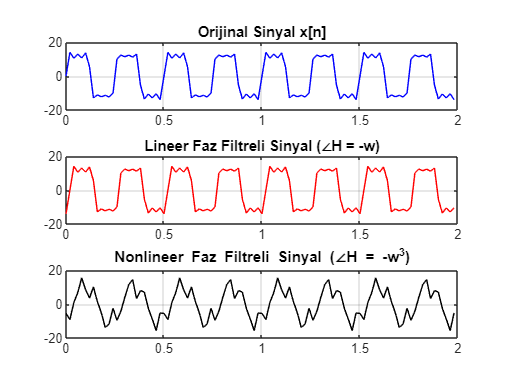

soundsc(quantized, Fs);


%% (f) Üç Sinüzoid + Faz Filtresi Uygulaması

% Parametreler
Fs = 50; T = 2;
n = 0:1/Fs:T-(1/Fs);
L = length(n);
w = 2*pi*(0:L-1)/L;   % normalize frekans

% Üç sinüzoidli x[n]
x = 15*sin(2*pi*4*n) + 5*sin(2*pi*12*n) + 3*sin(2*pi*20*n);

% FFT ile spektrum
X = fft(x);

% Faz filtresi 1: lineer faz (-w)
H1 = exp(-1i * w);       
Y1 = X .* H1;
y1 = real(ifft(Y1));

% Faz filtresi 2: non-lineer faz (-w^3)
H2 = exp(-1i * w.^3);    
Y2 = X .* H2;
y2 = real(ifft(Y2));

% Tüm sinyalleri çiz
figure;
subplot(3,1,1);
plot(n, x, 'b'); title('Orijinal Sinyal x[n]'); grid on;

subplot(3,1,2);
plot(n, y1, 'r'); title('Lineer Faz Filtreli Sinyal (∠H = -w)'); grid on;

subplot(3,1,3);
plot(n, y2, 'k'); title('Nonlineer Faz Filtreli Sinyal (∠H = -w^3)'); grid on;



%%(g) sound1.wav için Faz Filtresi Uygulaması

% Ses dosyasını oku
[soundData, Fs] = audioread('C:\Users\mehme\Desktop\lab3_prelab\sound.mp3');
%%[soundData, Fs] = audioread('sound1.wav');

% Mono hale getir
if size(soundData,2) > 1
    soundData = soundData(:,1); 
end

% Uzunluk ve normalize frekans ekseni
L = length(soundData);
w = 2*pi*(0:L-1)/L;

% FFT
X = fft(soundData);

% Lineer faz filtresi (∠H = -w)
H1 = exp(-1i * w);
Y1 = X .* H1;

Requested 229872x229872 (787.4GB) array exceeds maximum array size preference (7.7GB). This might cause MATLAB to become unresponsive.

Related documentation

y1 = real(ifft(Y1));

% Non-lineer faz filtresi (∠H = -w^3)
H2 = exp(-1i * w.^3);
Y2 = X .* H2;
y2 = real(ifft(Y2));

% Zaman ekseni
t = (0:L-1)/Fs;

% Grafikle göster
figure;
subplot(3,1,1);
plot(t, soundData); title('Orijinal sound1.wav'); grid on;

subplot(3,1,2);
plot(t, y1); title('Lineer Fazlı Filtreli'); grid on;

subplot(3,1,3);
plot(t, y2); title('Nonlineer Fazlı Filtreli'); grid on;

% Sesleri sırayla çal
disp('Orijinal ses çalınıyor...');
soundsc(soundData, Fs); pause(3);

disp('Lineer fazlı ses çalınıyor...');
soundsc(y1, Fs); pause(3);

disp('Non-lineer fazlı ses çalınıyor...');
soundsc(y2, Fs);
